Signal duration: 300.40 seconds


Number of samples: 75100


Sampling frequency: 250 Hz


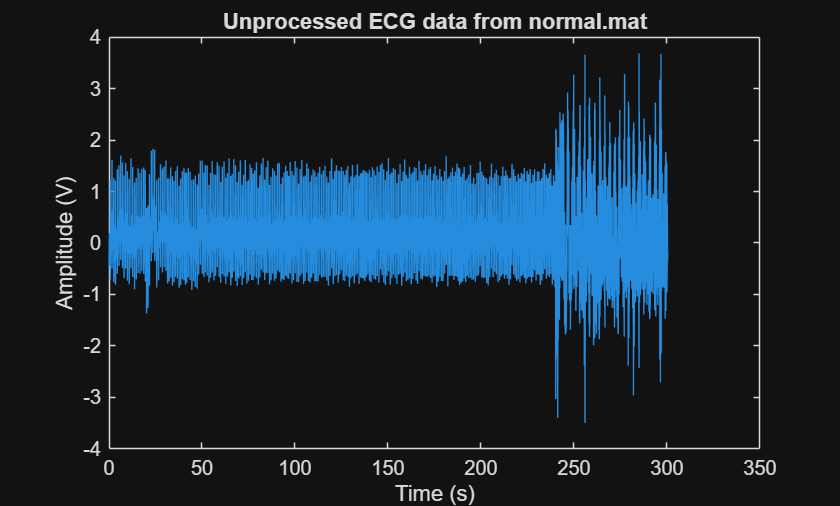

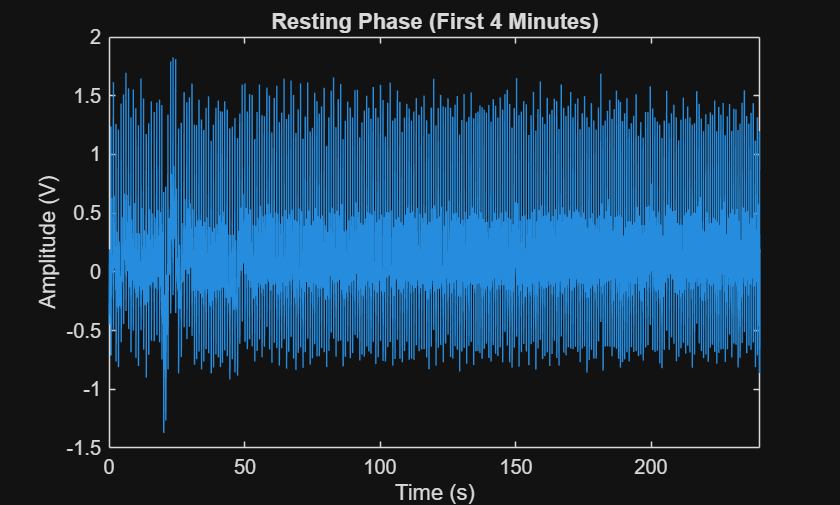

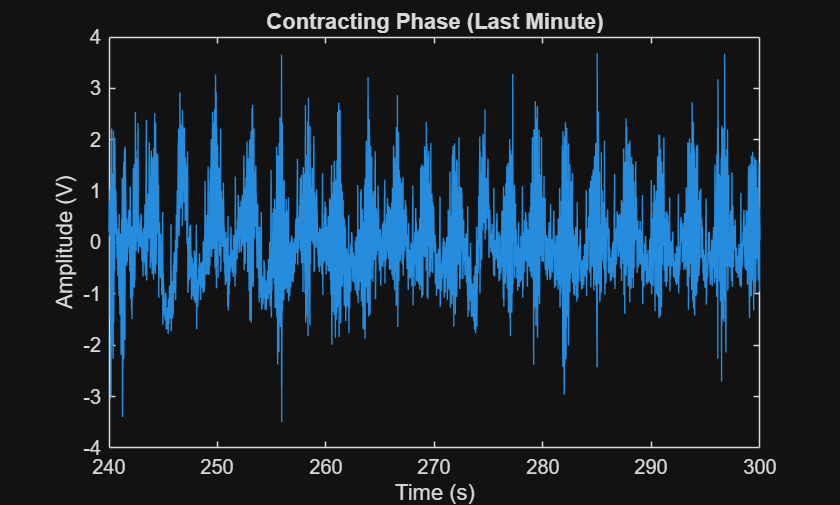

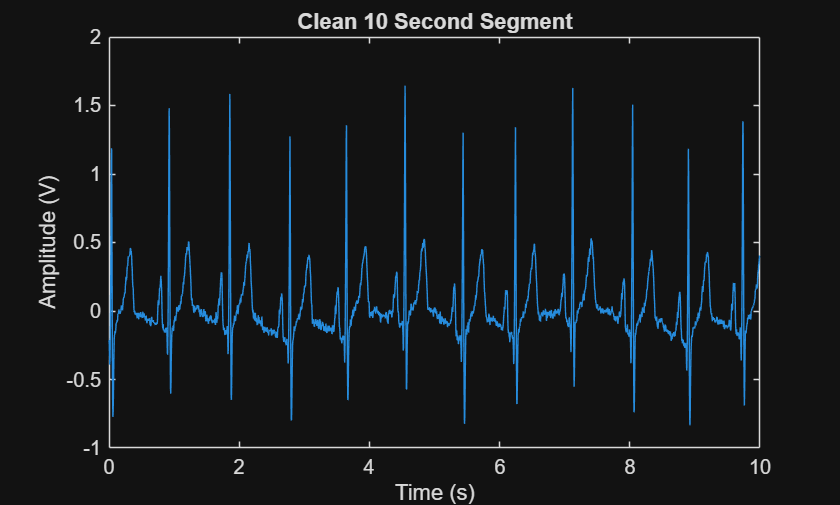

% Load the normal ECG data
load('data/normal.mat');


t = normal(:,1);
x = normal(:,2);

% Display basic information about the data
fprintf('Sampling frequency: %.2f Hz\n', 1/mean(diff(t)));
fprintf('Recording duration: %.2f seconds\n', t(end) - t(1));
fprintf('Number of samples: %d\n', length(t));

% Convert the ECG values from volts to millivolts for easier analysis
x_mV = x * 1000;

% Calculate the differences between consecutive values
diff_vals = diff(unique(x_mV));

% Find the minimum non-zero difference
min_diff = min(diff_vals(diff_vals > 0));

% Check if the resolution matches 16-bit quantization
adc_range = 2*5; % ±5V range = 10V total
resolution_16bit = adc_range/2^16 * 1000; % in mV, accounting for gain of 1000

fprintf('Minimum difference between values: %.6f mV\n', min_diff);
fprintf('Expected resolution for 16-bit ADC: %.6f mV\n', resolution_16bit);

## Task 5

% First 4 minutes (240 seconds) contain clean data, last minute contains noise
clean_start = 60; % Starting at 1 minute to avoid initial artifacts
clean_end = clean_start + 10; % 10-second segment
noisy_start = 250; % Starting in the noisy section
noisy_end = noisy_start + 10; % 10-second segment

% Extract segments
clean_indices = t >= clean_start & t <= clean_end;
noisy_indices = t >= noisy_start & t <= noisy_end;

t_clean = t(clean_indices);
ecg_clean = x(clean_indices);
t_noisy = t(noisy_indices);
ecg_noisy = x(noisy_indices);

% Time domain plots
figure('Name', 'Time Domain Analysis', 'Position', [100, 100, 1000, 600]);

subplot(2,1,1);
plot(t_clean, ecg_clean);
title('Clean ECG Segment');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;

subplot(2,1,2);
plot(t_noisy, ecg_noisy);
title('Noisy ECG Segment');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;

% Frequency domain analysis
% Calculate sampling frequency
Fs = 1/mean(diff(t));

% Perform FFT on clean segment
N_clean = length(ecg_clean);
Y_clean = fft(ecg_clean);
P2_clean = abs(Y_clean/N_clean);
P1_clean = P2_clean(1:floor(N_clean/2+1));
P1_clean(2:end-1) = 2*P1_clean(2:end-1);
f_clean = Fs*(0:(N_clean/2))/N_clean;

% Perform FFT on noisy segment
N_noisy = length(ecg_noisy);
Y_noisy = fft(ecg_noisy);
P2_noisy = abs(Y_noisy/N_noisy);
P1_noisy = P2_noisy(1:floor(N_noisy/2+1));
P1_noisy(2:end-1) = 2*P1_noisy(2:end-1);
f_noisy = Fs*(0:(N_noisy/2))/N_noisy;

% Convert to dB
P1_clean_dB = 20*log10(P1_clean + eps); % Adding eps to avoid log(0)
P1_noisy_dB = 20*log10(P1_noisy + eps);

% Plot frequency domain
figure('Name', 'Frequency Domain Analysis', 'Position', [100, 100, 1000, 600]);

subplot(2,1,1);
plot(f_clean, P1_clean_dB);
title('Clean ECG Segment - Frequency Domain');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
xlim([0 125]); % Only show up to Nyquist frequency

subplot(2,1,2);
plot(f_noisy, P1_noisy_dB);
title('Noisy ECG Segment - Frequency Domain');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
xlim([0 125]); % Only show up to Nyquist frequency

## Task 5

lowCutoff = 0.5;  % Hz - to remove baseline wander but preserve low frequency components
highCutoff = 45;  % Hz - to remove high frequency noise but preserve QRS morphology

% Normalized cutoff frequencies
Wn = [lowCutoff, highCutoff]/(Fs/2);

% Design a 2nd order Butterworth bandpass filter
[b, a] = butter(2, Wn, 'bandpass');

% Plot the filter responses
figure('Name', 'Filter Response', 'Position', [100, 100, 1000, 600]);

% Impulse response
subplot(2,1,1);
[h, t_imp] = impz(b, a, 100, Fs);
stem(t_imp, h);
title('Impulse Response of Bandpass Filter');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% Frequency response
subplot(2,1,2);
[h, f] = freqz(b, a, 1024, Fs);
plot(f, 20*log10(abs(h)));
title('Frequency Response of Bandpass Filter');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
xlim([0 125]);

## Task 6

ecg_clean_filtered = filtfilt(b, a, ecg_clean);

% Apply filter to noisy segment
ecg_noisy_filtered = filtfilt(b, a, ecg_noisy);

% Time domain comparison
figure('Name', 'Filtered ECG - Time Domain', 'Position', [100, 100, 1000, 800]);

subplot(2,2,1);
plot(t_clean, ecg_clean);
title('Original Clean ECG');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;

subplot(2,2,2);
plot(t_clean, ecg_clean_filtered);
title('Filtered Clean ECG');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;

subplot(2,2,3);
plot(t_noisy, ecg_noisy);
title('Original Noisy ECG');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;

subplot(2,2,4);
plot(t_noisy, ecg_noisy_filtered);
title('Filtered Noisy ECG');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;

% Frequency domain comparison (clean)
% Perform FFT on filtered clean segment
Y_clean_filtered = fft(ecg_clean_filtered);
P2_clean_filtered = abs(Y_clean_filtered/N_clean);
P1_clean_filtered = P2_clean_filtered(1:floor(N_clean/2+1));
P1_clean_filtered(2:end-1) = 2*P1_clean_filtered(2:end-1);
P1_clean_filtered_dB = 20*log10(P1_clean_filtered + eps);

% Frequency domain comparison (noisy)
% Perform FFT on filtered noisy segment
Y_noisy_filtered = fft(ecg_noisy_filtered);
P2_noisy_filtered = abs(Y_noisy_filtered/N_noisy);
P1_noisy_filtered = P2_noisy_filtered(1:floor(N_noisy/2+1));
P1_noisy_filtered(2:end-1) = 2*P1_noisy_filtered(2:end-1);
P1_noisy_filtered_dB = 20*log10(P1_noisy_filtered + eps);

% Plot frequency domain comparison
figure('Name', 'Filtered ECG - Frequency Domain', 'Position', [100, 100, 1000, 800]);

subplot(2,2,1);
plot(f_clean, P1_clean_dB);
title('Original Clean ECG Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
xlim([0 125]);

subplot(2,2,2);
plot(f_clean, P1_clean_filtered_dB);
title('Filtered Clean ECG Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
xlim([0 125]);

subplot(2,2,3);
plot(f_noisy, P1_noisy_dB);
title('Original Noisy ECG Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
xlim([0 125]);

subplot(2,2,4);
plot(f_noisy, P1_noisy_filtered_dB);
title('Filtered Noisy ECG Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
xlim([0 125]);


## Task 7

## Task 8

## Task 9

%% Task 9: Automated heart rate detection

% Filter the entire ECG signal
ecg_filtered = filtfilt(b, a, x);

% Detect R peaks using a simple threshold-based approach
% We'll first enhance the QRS complex
% Derivative to emphasize the rapid upslope of the R wave
ecg_diff = diff(ecg_filtered);
ecg_diff = [0; ecg_diff]; % Add zero to maintain original length

% Square the signal to enhance large values (R peaks)
ecg_squared = ecg_diff.^2;

% Moving average to integrate over a window
window_size = round(0.08 * Fs); % 80 ms window
b_ma = ones(1, window_size)/window_size;
ecg_integrated = filter(b_ma, 1, ecg_squared);

% Apply to clean segment for demonstration
ecg_clean_integrated = ecg_integrated(clean_indices);

% Find peaks in the integrated signal
min_distance = round(0.2 * Fs); % Minimum distance between peaks (200 ms)
min_height = 0.5 * max(ecg_clean_integrated); % Adaptive threshold
[~, r_locs_clean] = findpeaks(ecg_clean_integrated, 'MinPeakHeight', min_height, 'MinPeakDistance', min_distance);

% Convert peak locations to time
r_times_clean = t_clean(r_locs_clean);

% Calculate heart rate from R-R intervals
rr_intervals = diff(r_times_clean);
heart_rate_clean = 60 ./ rr_intervals; % Convert to BPM

% Calculate average heart rate
avg_heart_rate_clean = 60 / mean(rr_intervals);

% Display results
fprintf('Manually estimated heart rate (Task 8): ~75 BPM (example value)\n');
fprintf('Automated average heart rate: %.1f BPM\n', avg_heart_rate_clean);

% Plot the R peak detection on clean segment
figure('Name', 'R Peak Detection - Clean Segment', 'Position', [100, 100, 1000, 800]);

subplot(3,1,1);
plot(t_clean, ecg_clean_filtered);
hold on;
plot(r_times_clean, ecg_clean_filtered(r_locs_clean), 'ro', 'MarkerSize', 10);
title('Filtered ECG with Detected R Peaks');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;

subplot(3,1,2);
plot(t_clean, ecg_clean_integrated);
hold on;
plot(r_times_clean, ecg_clean_integrated(r_locs_clean), 'ro', 'MarkerSize', 10);
title('Integrated Signal with Detected Peaks');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(3,1,3);
plot(r_times_clean(1:end-1), heart_rate_clean, 'o-');
title('Beat-to-Beat Heart Rate');
xlabel('Time (s)');
ylabel('Heart Rate (BPM)');
grid on;
ylim([40 120]); % Typical heart rate range

## Task 10

% Apply the R peak detection to the entire signal
% We'll use a sliding window approach for more robust analysis
window_length = 3; % seconds
window_step = 1; % seconds
num_windows = floor((t(end) - t(1) - window_length) / window_step) + 1;

% Prepare arrays for results
window_times = zeros(num_windows, 1);
heart_rates = zeros(num_windows, 1);

% Process each window
for i = 1:num_windows
    window_start = t(1) + (i-1) * window_step;
    window_end = window_start + window_length;
    
    % Find indices for this window
    window_indices = t >= window_start & t <= window_end;
    
    % Extract window data
    t_window = t(window_indices);
    ecg_integrated_window = ecg_integrated(window_indices);
    
    % Find peaks in this window
    min_height = 0.5 * max(ecg_integrated_window); % Adaptive threshold
    [~, r_locs_window] = findpeaks(ecg_integrated_window, 'MinPeakHeight', min_height, 'MinPeakDistance', min_distance);
    
    % If fewer than 2 peaks found, skip this window
    if length(r_locs_window) < 2
        heart_rates(i) = NaN;
    else
        % Calculate heart rate from R-R intervals
        r_times_window = t_window(r_locs_window);
        rr_intervals_window = diff(r_times_window);
        heart_rate_window = 60 / mean(rr_intervals_window);
        
        % Store results
        heart_rates(i) = heart_rate_window;
    end
    
    % Store window midpoint time
    window_times(i) = window_start + window_length/2;
end

% Plot heart rate over time
figure('Name', 'Heart Rate Over Time', 'Position', [100, 100, 800, 400]);
plot(window_times, heart_rates, 'o-');
title('Heart Rate Variation Throughout Recording');
xlabel('Time (s)');
ylabel('Heart Rate (BPM)');
grid on;
ylim([40 120]); % Typical heart rate range

## Task 11

## Task 12

clear;
% Load arrhythmia data file
load('data/n_422.mat');
% Assuming data is stored in a variable called 'val'
% If the variable name is different, adjust accordingly

% Create time vector (sampling frequency 250 Hz)
Fs_arr = 250;
t_arr = (0:length(n_422)-1)/Fs_arr;

% Convert from quantization steps to voltage (5 µV per step)
ecg_arr = n_422 * 5e-6; % Convert to volts

% Find the transition point around 42 seconds
normal_start = 20; % seconds
normal_end = normal_start + 10;
arrhythmia_start = 45; % seconds (after onset at ~42s)
arrhythmia_end = arrhythmia_start + 10;

% Extract segments
normal_indices = t_arr >= normal_start & t_arr <= normal_end;
arrhythmia_indices = t_arr >= arrhythmia_start & t_arr <= arrhythmia_end;

t_normal = t_arr(normal_indices);
ecg_normal = ecg_arr(normal_indices);
t_arrhythmia = t_arr(arrhythmia_indices);
ecg_arrhythmia = ecg_arr(arrhythmia_indices);

% Apply bandpass filtering (similar to before)
[b_arr, a_arr] = butter(4, [0.5, 40]/(Fs_arr/2), 'bandpass');
ecg_normal_filtered = filtfilt(b_arr, a_arr, ecg_normal);
ecg_arrhythmia_filtered = filtfilt(b_arr, a_arr, ecg_arrhythmia);

% Plot time domain comparison
figure('Name', 'Normal vs Arrhythmia - Time Domain', 'Position', [100, 100, 1000, 600]);

subplot(2,1,1);
plot(t_normal, ecg_normal_filtered);
title('Normal ECG Segment (Filtered)');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;

subplot(2,1,2);
plot(t_arrhythmia, ecg_arrhythmia_filtered);
title('Arrhythmia ECG Segment (Filtered)');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;

% Frequency domain analysis
% Normal segment
N_normal = length(ecg_normal_filtered);
Y_normal = fft(ecg_normal_filtered);
P2_normal = abs(Y_normal/N_normal);
P1_normal = P2_normal(1:floor(N_normal/2+1));
P1_normal(2:end-1) = 2*P1_normal(2:end-1);
f_normal = Fs_arr*(0:(N_normal/2))/N_normal;
P1_normal_dB = 20*log10(P1_normal + eps);

% Arrhythmia segment
N_arrhythmia = length(ecg_arrhythmia_filtered);
Y_arrhythmia = fft(ecg_arrhythmia_filtered);
P2_arrhythmia = abs(Y_arrhythmia/N_arrhythmia);
P1_arrhythmia = P2_arrhythmia(1:floor(N_arrhythmia/2+1));
P1_arrhythmia(2:end-1) = 2*P1_arrhythmia(2:end-1);
f_arrhythmia = Fs_arr*(0:(N_arrhythmia/2))/N_arrhythmia;
P1_arrhythmia_dB = 20*log10(P1_arrhythmia + eps);

% Plot frequency domain comparison
figure('Name', 'Normal vs Arrhythmia - Frequency Domain', 'Position', [100, 100, 1000, 600]);

subplot(2,1,1);
plot(f_normal, P1_normal_dB);
title('Normal ECG Segment - Frequency Domain');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
xlim([0 50]);

subplot(2,1,2);
plot(f_arrhythmia, P1_arrhythmia_dB);
title('Arrhythmia ECG Segment - Frequency Domain');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
xlim([0 50]);

## Task 13

function detection_result = detect_arrhythmia(ecg_segment, Fs)
    % Apply bandpass filter
    [b, a] = butter(4, [0.5, 40]/(Fs/2), 'bandpass');
    ecg_filtered = filtfilt(b, a, ecg_segment);
    
    % Feature 1: Regularity of R peaks
    % Detect R peaks using threshold
    ecg_diff = diff([0; ecg_filtered]);
    ecg_squared = ecg_diff.^2;
    window_size = round(0.08 * Fs);
    b_ma = ones(1, window_size)/window_size;
    ecg_integrated = filter(b_ma, 1, ecg_squared);
    
    min_distance = round(0.2 * Fs);
    min_height = 0.3 * max(ecg_integrated);
    [~, r_locs] = findpeaks(ecg_integrated, 'MinPeakHeight', min_height, 'MinPeakDistance', min_distance);
    
    % Calculate R-R interval variability
    if length(r_locs) >= 3
        rr_intervals = diff(r_locs) / Fs;
        rr_std = std(rr_intervals);
        regularity_feature = rr_std;
    else
        % Few or no R peaks detected, could indicate arrhythmia
        regularity_feature = 1.0; % High value indicates irregularity
    end
    
    % Feature 2: Spectral concentration
    Y = fft(ecg_filtered);
    P2 = abs(Y/length(ecg_filtered));
    P1 = P2(1:floor(length(ecg_filtered)/2+1));
    P1(2:end-1) = 2*P1(2:end-1);
    f = Fs*(0:(length(ecg_filtered)/2))/length(ecg_filtered);
    
    % Find dominant frequency
    [~, max_idx] = max(P1(f > 0.5 & f < 40));
    freq_indices = find(f > 0.5 & f < 40);
    dominant_freq = f(freq_indices(max_idx));
    
    % Calculate power in VF band (4-7 Hz)
    vf_band_indices = f >= 4 & f <= 7;
    normal_band_indices = f >= 0.5 & f <= 3;
    
    vf_power = sum(P1(vf_band_indices));
    normal_power = sum(P1(normal_band_indices));
    
    spectral_ratio = vf_power / normal_power;
    
    % Feature 3: Signal complexity (using sample entropy or similar)
    % Simplified complexity measure: standard deviation of the filtered signal
    complexity = std(ecg_filtered);
    
    % Combine features for decision
    % These thresholds would need to be tuned based on training data
    if (regularity_feature > 0.3 && spectral_ratio > 2.0) || (dominant_freq > 4.0 && dominant_freq < 7.0)
        result = 1; % Arrhythmia detected
    else
        result = 0; % Normal rhythm
    end
    
    % Return result and features for analysis
    detection_result = struct('result', result, ...
                             'regularity', regularity_feature, ...
                             'spectral_ratio', spectral_ratio, ...
                             'dominant_freq', dominant_freq, ...
                             'complexity', complexity);
end

%% Task 14: Evaluate detector performance on n_422.mat

% Apply detector on sliding windows of the signal
window_length = 3; % seconds
window_step = 0.5; % seconds
num_windows_arr = floor((t_arr(end) - window_length) / window_step) + 1;

% Prepare arrays for results
detection_times = zeros(num_windows_arr, 1);
detection_results = zeros(num_windows_arr, 1);
detection_features = cell(num_windows_arr, 1);

% Process each window
for i = 1:num_windows_arr
    window_start = (i-1) * window_step;
    window_end = window_start + window_length;
    
    % Find indices for this window
    window_indices = t_arr >= window_start & t_arr <= window_end;
    
    % Extract window data
    ecg_window = ecg_arr(window_indices);
    
    % Apply detector
    result = detect_arrhythmia(ecg_window, Fs_arr);
    
    % Store results
    detection_times(i) = window_start + window_length/2;
    detection_results(i) = result.result;
    detection_features{i} = result;
end

% Plot detection results
figure('Name', 'Arrhythmia Detection Results', 'Position', [100, 100, 1000, 800]);

% Plot original ECG
subplot(3,1,1);
plot(t_arr, ecg_arr);
title('Original ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;
xlim([0 300]); % Show full 5 minutes

% Plot detection result
subplot(3,1,2);
stairs(detection_times, detection_results);
title('Arrhythmia Detection (1 = Arrhythmia, 0 = Normal)');
xlabel('Time (s)');
ylabel('Detection Result');
ylim([-0.1 1.1]);
grid on;
xlim([0 300]);

% Extract features for plotting
spectral_ratios = zeros(num_windows_arr, 1);
dominant_freqs = zeros(num_windows_arr, 1);
for i = 1:num_windows_arr
    spectral_ratios(i) = detection_features{i}.spectral_ratio;
    dominant_freqs(i) = detection_features{i}.dominant_freq;
end

% Plot key feature
subplot(3,1,3);
plot(detection_times, spectral_ratios);
title('Spectral Ratio Feature (VF Power / Normal Power)');
xlabel('Time (s)');
ylabel('Ratio');
grid on;
xlim([0 300]);

% Ground truth (known transition at around 42 seconds)
% Add a vertical line at the known transition point
for i = 1:3
    subplot(3,1,i);
    hold on;
    line([42 42], get(gca, 'YLim'), 'Color', 'r', 'LineStyle', '--', 'LineWidth', 2);
    hold off;
end


## Task 15

% Load the second arrhythmia file
load('data/n_421.mat');
% Assuming data is stored in a variable called 'val'
% If the variable name is different, adjust accordingly

% Create time vector (sampling frequency 250 Hz)
t_arr2 = (0:length(n_422)-1)/Fs_arr;

% Convert from quantization steps to voltage (5 µV per step)
ecg_arr2 = n_422 * 5e-6; % Convert to volts

% Apply detector on sliding windows
num_windows_arr2 = floor((t_arr2(end) - window_length) / window_step) + 1;

% Prepare arrays for results
detection_times2 = zeros(num_windows_arr2, 1);
detection_results2 = zeros(num_windows_arr2, 1);
detection_features2 = cell(num_windows_arr2, 1);

% Process each window
for i = 1:num_windows_arr2
    window_start = (i-1) * window_step;
    window_end = window_start + window_length;
    
    % Find indices for this window
    window_indices = t_arr2 >= window_start & t_arr2 <= window_end;
    
    % Extract window data
    ecg_window = ecg_arr2(window_indices);
    
    % Apply detector
    result = detect_arrhythmia(ecg_window, Fs_arr);
    
    % Store results
    detection_times2(i) = window_start + window_length/2;
    detection_results2(i) = result.result;
    detection_features2{i} = result;
end

% Plot analysis of n_421.mat
figure('Name', 'Visual Examination of n_421.mat', 'Position', [100, 100, 1000, 600]);

subplot(2,1,1);
plot(t_arr2, ecg_arr2);
title('ECG Signal from n\_421.mat');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;
xlim([0 300]); % Show full 5 minutes

% Apply the same bandpass filter
ecg_arr2_filtered = filtfilt(b_arr, a_arr, ecg_arr2);

subplot(2,1,2);
plot(t_arr2, ecg_arr2_filtered);
title('Filtered ECG Signal from n\_421.mat');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;
xlim([0 300]);

% Plot detection results
figure('Name', 'Arrhythmia Detection Results for n_421.mat', 'Position', [100, 100, 1000, 600]);

subplot(2,1,1);
stairs(detection_times2, detection_results2);
title('Arrhythmia Detection (1 = Arrhythmia, 0 = Normal)');
xlabel('Time (s)');
ylabel('Detection Result');
ylim([-0.1 1.1]);
grid on;
xlim([0 300]);

% Extract features for plotting
spectral_ratios2 = zeros(num_windows_arr2, 1);
dominant_freqs2 = zeros(num_windows_arr2, 1);
for i = 1:num_windows_arr2
    spectral_ratios2(i) = detection_features2{i}.spectral_ratio;
    dominant_freqs2(i) = detection_features2{i}.dominant_freq;
end

subplot(2,1,2);
plot(detection_times2, spectral_ratios2);
title('Spectral Ratio Feature (VF Power / Normal Power)');
xlabel('Time (s)');
ylabel('Ratio');
grid on;
xlim([0 300]);
